# **NUMERICALLY** solve the inverse Kinematics of a 4-dof Robotic manipulator

In this task we're going to ***NUMERICALLY*** solve the inverse kinematics for a 4-dof robotic manipulator, ie: $(X_E,Y_E,Z_E) \longrightarrow g(X_E, Y_E,Z_E) \longrightarrow (\theta_1, \theta_2, \theta_3, \theta_4)$.   The system that we're going to explore is shown below:

     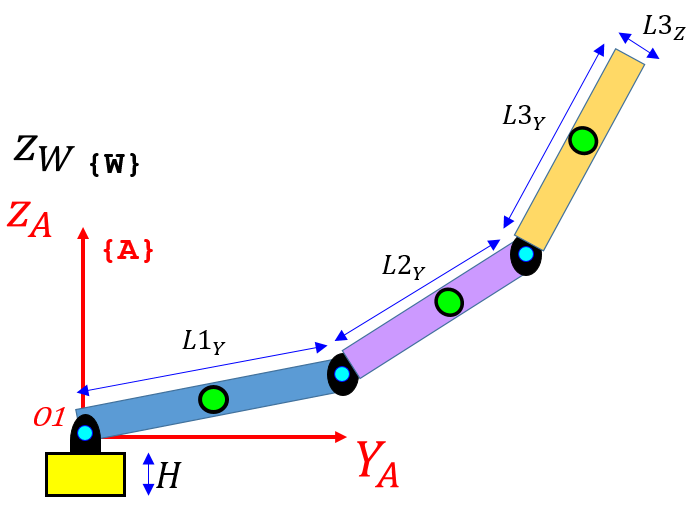   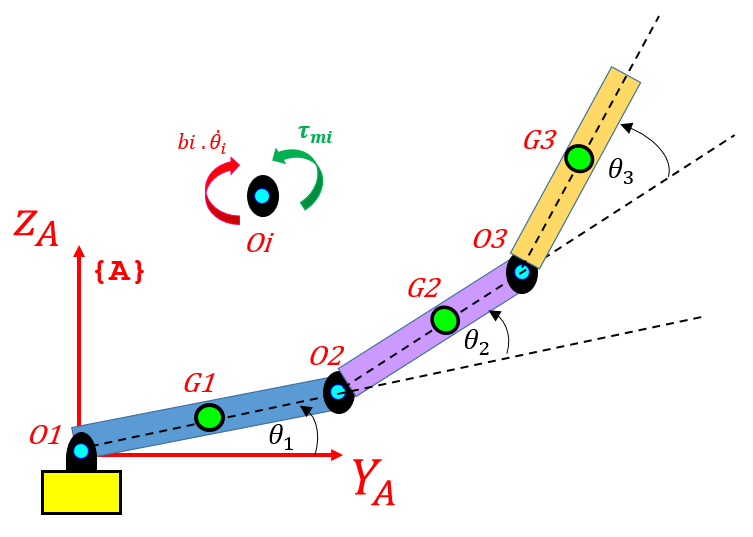   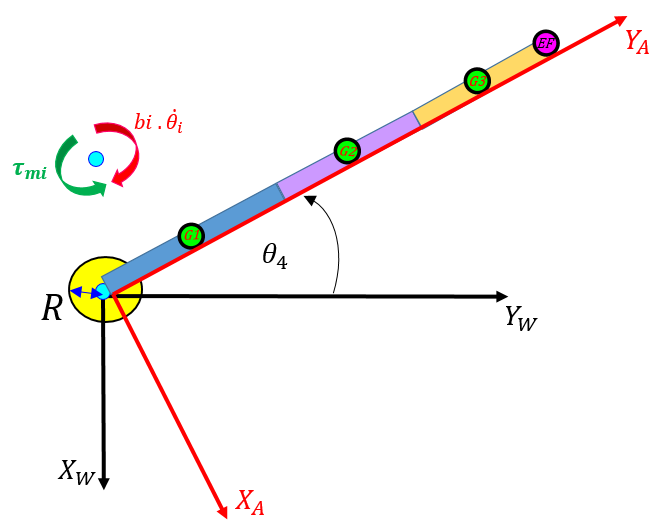

`Bradley Horton : 01-Aug-2016, bradley.horton@mathworks.com.au`      

## Defining some geometry parameters:

syms   L1Y_s L2Y_s L3Y_s 

syms   theta1   
syms   theta2 
syms   theta3
syms   theta4 

syms XE YE ZE

## Compute the FORWARD  Kinematics:  $(\theta_1, \theta_2, \theta_3, \theta_4)
\longrightarrow
f(\theta_1, \theta_2, \theta_3, \theta_4)
\longrightarrow 
(X_E,Y_E,Z_E) $

Let's define the X,Y,Z position of the End Effector (EF):

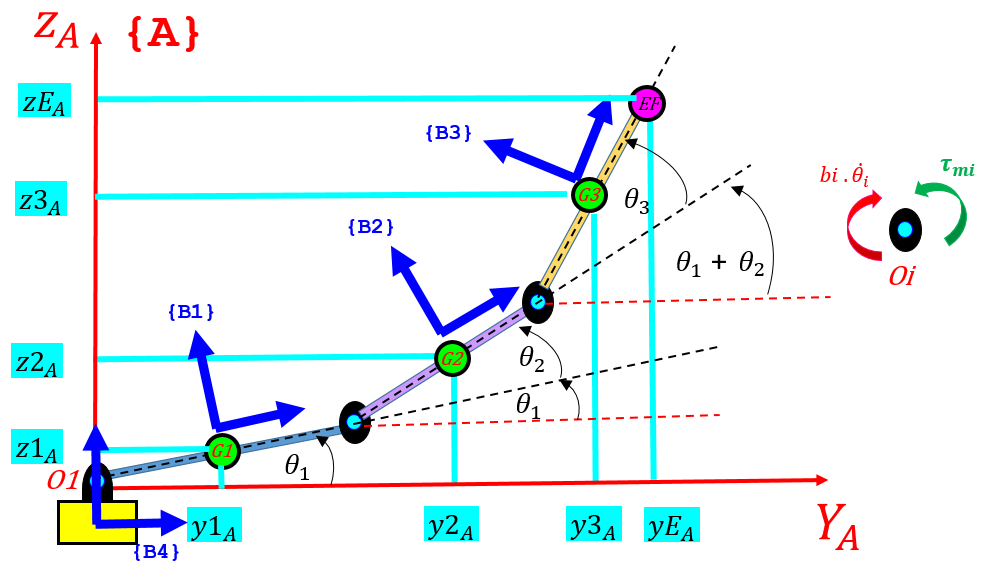     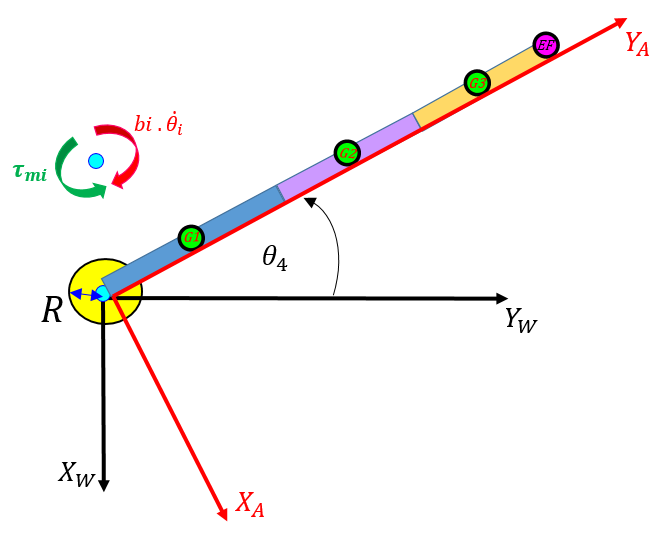

First, let's define the x,y,z position of the End Effector (EF) in terms of the {A}-Frame.  And after we've done this, we'll convert these co-ordinates into our inertial {W}-frame:

A few utility angles to help us:

alpha           = theta1 + theta2;
beta            = theta1 + theta2 + theta3;

OK: so what are the x,y,z co-ordinates of the end effector in components of the {A}-Frame ?

AF_pos_eff      = sym([0;0;0]);
AF_pos_eff(2,1) = L1Y_s*cos(theta1) + L2Y_s*cos(alpha) + L3Y_s*cos(beta);
AF_pos_eff(3,1) = L1Y_s*sin(theta1) + L2Y_s*sin(alpha) + L3Y_s*sin(beta);

We can now convert these {A}-Frame co-ordinates into their corresponding {W}-frame co-ordinates using the following transformation:

   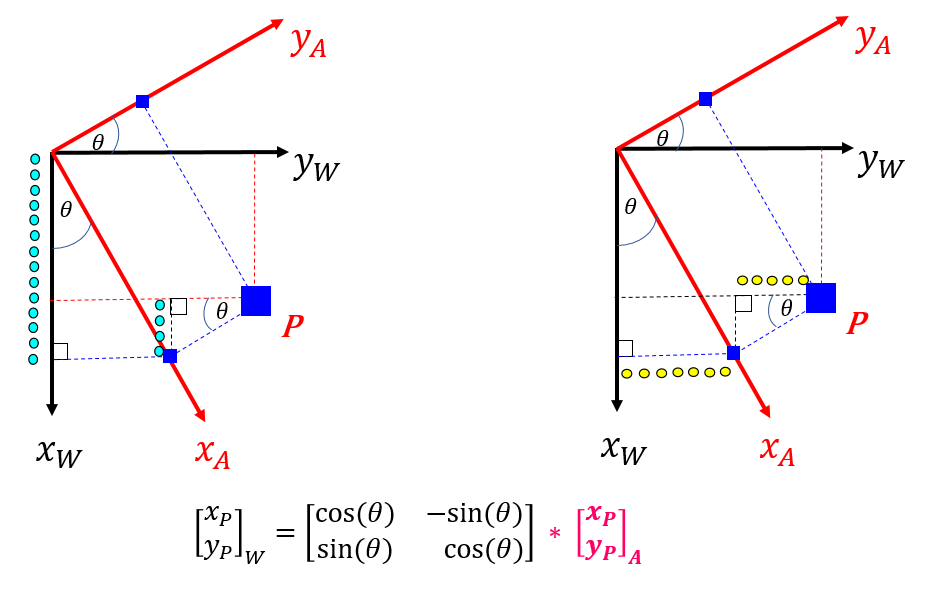

wRa = [ cos(theta4),  -sin(theta4),   0;
        sin(theta4),   cos(theta4),   0;
                  0,             0,   1 ];

So our {W}-Frame end effector co-ordinates are:

WF_pos_eff = wRa * AF_pos_eff;             

Rip out the X,Y,Z elements:

the_XE_RHS = WF_pos_eff(1);
the_YE_RHS = WF_pos_eff(2);
the_ZE_RHS = WF_pos_eff(3);

And I can create a MATLAB function of these END EFFECTOR  forward kinematics:

- 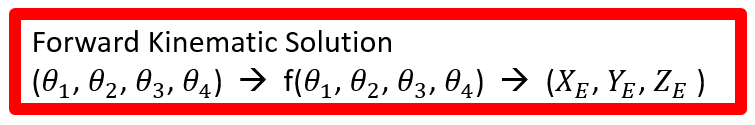

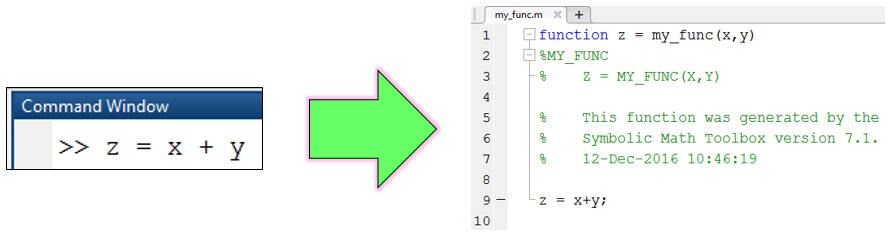

matlabFunction([the_XE_RHS, the_YE_RHS, the_ZE_RHS], ...
               'File', 'bh_xyz_for_4dof_manip');

# Solving the Inverse KINEMATIC problem numerically  - part 1

To solve the INVERSE  Kinematics problem, ie:  $(X_E,Y_E,Z_E) \longrightarrow g(X_E, Y_E,Z_E) \longrightarrow (\theta_1, \theta_2, \theta_3, \theta_4)$. We're NOT going to look for a closed form analytical solution, but instead will approach the problem numerically.  We'll construct an optimization problem and then numerically solve it.  Since it's a numerical approach, we'll need to define values for some of our link geometry terms, so let's say that we have a robot with the following link lengths:

%% Define the LINK lengths
L1 = 0.75;
L2 = 0.5;
L3 = 0.25;

And say that that we know the ***desired*** XYZ trajectory that we want our END EFFECTOR to follow:

%% read data from EXCEL file
data_T = readtable('bh_hello_complete.xlsx','Sheet','COMP_SPLINE _4dof');

% downsample - say keep every 10th sample
data_T = data_T(1:10:end, :);

So plot the desired End Effector trajactory:

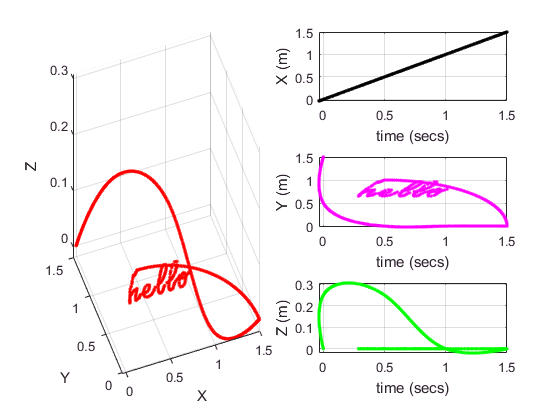

% plot it
figure;
subplot(3,2,[1 3 5]); 
                 plot3(data_T.XE, data_T.YE, data_T.ZE, 'r.');
                   axis tight; grid on; xlabel X; ylabel Y; zlabel Z; view([-20,34])
subplot(3,2,2);  plot(data_T.XE, data_T.XE,  'k.');
                   axis tight; grid on; xlabel('time (secs)'); ylabel('X (m)');
subplot(3,2,4);  plot(data_T.XE, data_T.YE,  'm.');
                   axis tight; grid on; xlabel('time (secs)'); ylabel('Y (m)');
subplot(3,2,6);  plot(data_T.XE, data_T.ZE,  'g.');
                   axis tight; grid on; xlabel('time (secs)'); ylabel('Z (m)');

So for every $\left\lbrace X_i ,\text{ }Y_i ,\text{ }Z_i \right\rbrace$ co-ordinate on this end effector trajectory, we'd like to determine what the required joint angles $\left\lbrace \theta_{1i\text{  }} ,\text{ }\theta_{2i} \text{ }\text{ },\text{ }\theta_{3i} \text{ },\text{ }\theta_{4i} \right\rbrace$ are.

# Solving the Inverse KINEMATIC problem numerically  - part 2

So we're going to formulate and then solve a constrained optimization problem.  The "general" form of a constrained optimization problem is shown below:

- 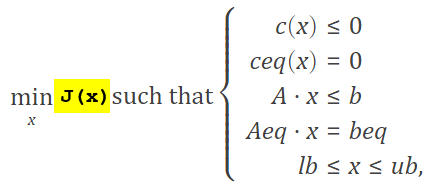   

- *J(*$x$*)* is a Cost function: it is the thing that we need to minimize. In our case we have:

- *J(*$x$*) = *$\left\|\text{ }DESIRED_XYZ−FORWARD_KINEMATICS\left(\theta_{1\text{ }} ,\theta_2 ,\theta_3 ,\theta_4 \right)\text{ }\right\|$, where: $\left\|\vec{p} \right\|$=$\sqrt{p_x^2 +\text{ }p_y^2 +p_z^2 }$

- *"*$x$*"* is a vector of design variables, ie: the things that we need to determine in order to minimize the cost function. In our case we have:

-  
$$x=\text{ }\left\lbrace \theta_1 ,\text{ }\theta_2 ,\text{ }\theta_3 ,\text{ }\theta_4 \text{ }\right\rbrace$$


Now we're going to use the `fmincon()` function to solve our optimization problem.  The format that we need to package our problem into is this:

- `x = fmincon( J_fun, x0, A, b, Aeq, beq, lb, ub, nonlcon, opts)`

So let's start setting up the problem to solve.

opts_T         = optimset;
opts_T.Display = 'off';

 Here are the lower and upper bounds for our 4 joint angles $\left\lbrace \theta_1 ,\text{ }\theta_2 ,\text{ }\theta_3 ,\text{ }\theta_4 \text{ }\right\rbrace$ - ***NOTE***, how we're asking for a solution where $\theta_1 \ge 0$

qa_lb = [   0;  -pi;   -pi;    -pi]; % LOWER bounds for angles
qa_ub = [  pi;   pi;    pi;     pi]; % UPPER bounds for angles

Here's an initial guess for what we think the solution is:

qa    = [ 0.5;  0.5;   0.5;    0.5]; % initial guess 

Now at the heart of this approach is the utilization of our FORWARD KINEMATICS function that we derived earlier:

-    `XYZ_EFF = bh_xyz_for_4dof_manip(L1Y_s,L2Y_s,L3Y_s,theta1,theta2,theta3,theta4)`

- 

For convenience, let's "parameterise" this FORWARD KINEMATICS function, by defining a function handle variable:

FWD_KIN_func = @(q) bh_xyz_for_4dof_manip(L1,L2,L3,q(1),q(2),q(3),q(4));

For every XYZ point of our end effector's trajectory, we need to find the values of $\left\lbrace \theta_1 ,\text{ }\theta_2 ,\text{ }\theta_3 ,\text{ }\theta_4 \text{ }\right\rbrace$ that "delivers" that XYZ co-ordinate.  So let's set up a FOR loop and process each point:

N      = size(data_T,1);  % number of points to process
Q_RES  = zeros(N, 4);     % container for collecting results 

*NOTE:  the next section of code takes 80 seconds to run on my laptop.*

% we'll loop over each point in our end effector's trajectory
for kk=1:N
    % the desired END EFFECTOR X,Y,Z position
    tgt_eff_pos = [data_T.XE(kk), data_T.YE(kk), data_T.ZE(kk)];
    
    % the cost function I want to minimize
    my_J = @(q)(  norm( tgt_eff_pos - FWD_KIN_func(q) )  );

    % starting guess, expect it close to previous solution
    q0 = qa; 
   
    % invoke our optimization solver:
    %x = fmincon( J_fun,  x0, A,b,Aeq,beq,    lb,    ub, nonlcon, opts)
    qa  = fmincon(my_J,   q0,[],[],[],[],  qa_lb, qa_ub, [],      opts_T);

    % store the angular results
    Q_RES(kk,:) = qa.' ;
    
    % echo our progress through the list of end effector points
    if(0==mod(kk,50))
      fprintf('\n .... kk=%4d of %4d',kk, N)    
    end   
end % for kk=1:N


 .... kk=  50 of  570


 .... kk= 100 of  570


 .... kk= 150 of  570


 .... kk= 200 of  570


 .... kk= 250 of  570


 .... kk= 300 of  570


 .... kk= 350 of  570


 .... kk= 400 of  570


 .... kk= 450 of  570


 .... kk= 500 of  570


 .... kk= 550 of  570

Plot the target END EFFECTOR position versus what we can deliver with our joint solution:

figure;
    plot3(      data_T.XE,         data_T.YE,       data_T.ZE, 'r.');

And now plot our delivered solution

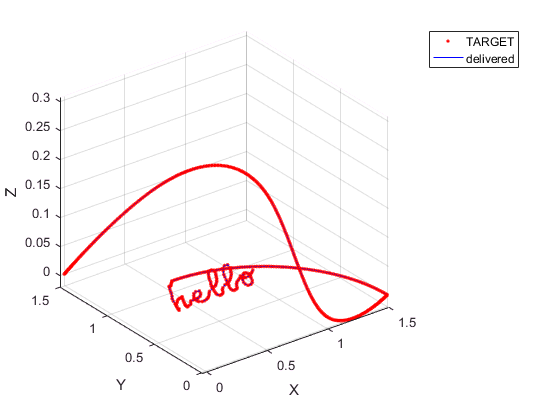

    our_sol_XYZ = bh_xyz_for_4dof_manip(L1,L2,L3, Q_RES(:,1), Q_RES(:,2), Q_RES(:,3), Q_RES(:,4) );

    hold on;
    plot3( our_sol_XYZ(:,1),  our_sol_XYZ(:,2),our_sol_XYZ(:,3), '-b');
    
    axis tight; grid on; xlabel X; ylabel Y; zlabel Z;
    legend({'TARGET','delivered'})

Plot the joint angles:

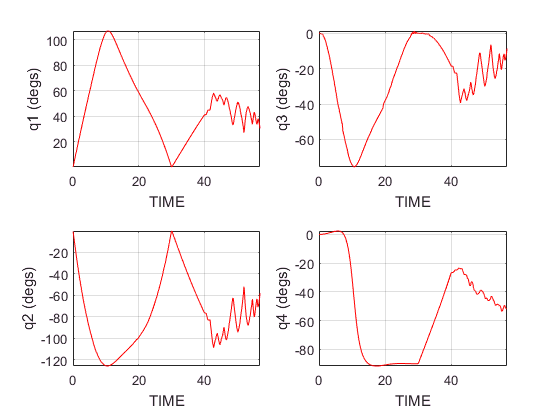

Q_degs_RES = (180/pi)*Q_RES;
T          = data_T.T;
figure;
subplot(2,2,1);  plot(T, Q_degs_RES(:,1), '-r'); 
                 grid on; xlabel TIME; ylabel('q1 (degs)'); axis tight;
subplot(2,2,3);  plot(T, Q_degs_RES(:,2), '-r'); 
                 grid on; xlabel TIME; ylabel('q2 (degs)'); axis tight;
subplot(2,2,2);  plot(T, Q_degs_RES(:,3), '-r'); 
                 grid on; xlabel TIME; ylabel('q3 (degs)'); axis tight;
subplot(2,2,4);  plot(T, Q_degs_RES(:,4), '-r'); 
                 grid on; xlabel TIME; ylabel('q4 (degs)'); axis tight;                 